# Two Way (Between) Analysis of Variance (ANOVA)

clear; clc; 
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Two Way (Between) Analysis of Variance (ANOVA)')

## 2-Way ANOVA Example

bloodpressure = [158,163,173,178,168,188,183,198,178,193,186,191,196,181,176,185,190,195,200,180];
biofeedback = [repelem("present", 10), repelem("absent", 10)];
drug = [repelem("present", 5), repelem("absent", 5), repelem("present", 5), repelem("absent", 5)]; 
bpDataTbl = table(bloodpressure', biofeedback', drug', 'variablenames', {'BP', 'BF', 'Drug'})

bpDataTbl = 20×3 table
    BP        BF          Drug   
    ___    _________    _________

    158    "present"    "present"
    163    "present"    "present"
    173    "present"    "present"
    178    "present"    "present"
    168    "present"    "present"
    188    "present"    "absent" 
    183    "present"    "absent" 
    198    "present"    "absent" 
    178    "present"    "absent" 
    193    "present"    "absent" 
    186    "absent"     "present"
    191    "absent"     "present"
    196    "absent"     "present"
    181    "absent"     "present"
    176    "absent"     "present"
    185    "absent"     "absent" 


myANOVA = fitlm(bpDataTbl, 'BP ~ BF*Drug')

myANOVA = Linear regression model:
    BP ~ 1 + BF*Drug

Estimated Coefficients:
                             Estimate      SE       tStat       pValue  
                             ________    ______    _______    __________

    (Intercept)                168       3.5355     47.518    1.1836e-18
    BF_absent                   18            5        3.6     0.0023992
    Drug_absent                 20            5          4      0.001032
    BF_absent:Drug_absent      -16       7.0711    -2.2627      0.037917


Number of observations: 20, Error degrees of freedom: 16
Root Mean Squared Error: 7.91
R-squared: 0.606,  Adjusted R-Squared: 0.532
F-statistic vs. constant model: 8.21, p-value = 0.00155

anova(myANOVA)

ans = 4×5 table
               SumSq    DF    MeanSq      F       pValue  
               _____    __    ______    _____    _________

    BF          500      1      500         8     0.012109
    Drug        720      1      720     11.52    0.0037059
    BF:Drug     320      1      320      5.12     0.037917
    Error      1000     16     62.5                       


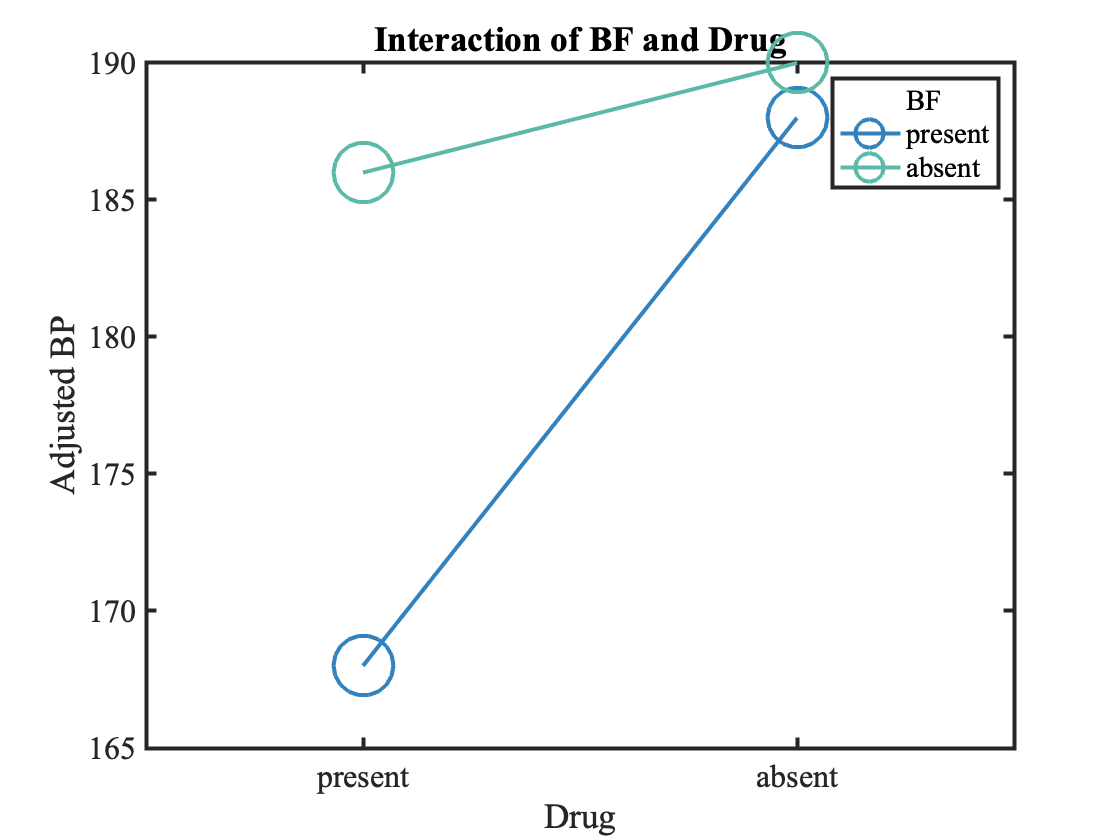

plotInteraction(myANOVA, 'BF', 'Drug', 'predictions')

## Testing Normality

[h, p, w] = swtest(bloodpressure(1:5)) % group 1 

h = logical
   0


p = 0.9672

w = 0.9868

[h, p, w] = swtest(bloodpressure(6:10)) % group 2 

h = logical
   0


p = 0.9672

w = 0.9868

[h, p, w] = swtest(bloodpressure(11:15)) % group 3 

h = logical
   0


p = 0.9672

w = 0.9868

[h, p, w] = swtest(bloodpressure(16:20)) % group 4

h = logical
   0


p = 0.9672

w = 0.9868

## Homogenous of Variance (Sphericity)

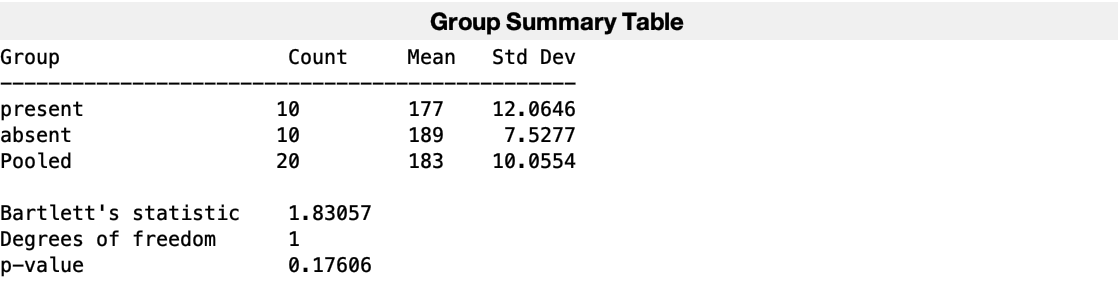

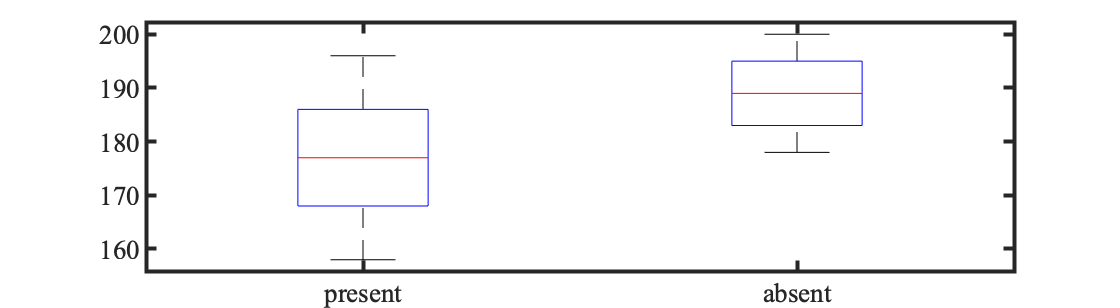

p = 0.1761

stats = struct with fields:
    chisqstat: 1.8306
           df: 1


% unsure for interaction effect, but I think p will always be 1 (don't
% quote me tho)
[p, stats] = vartestn(bloodpressure', drug)

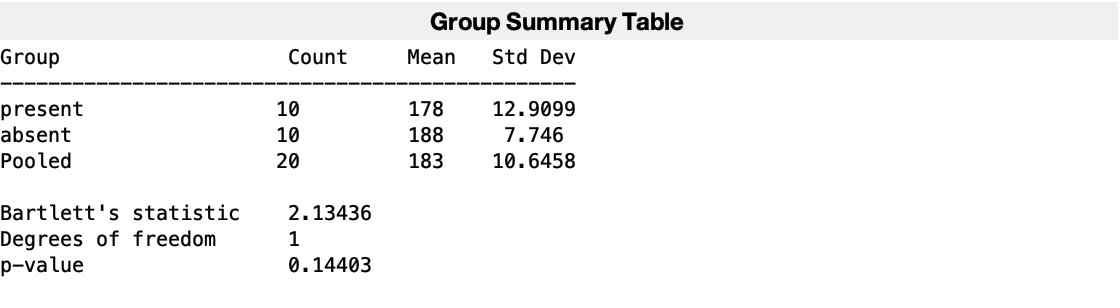

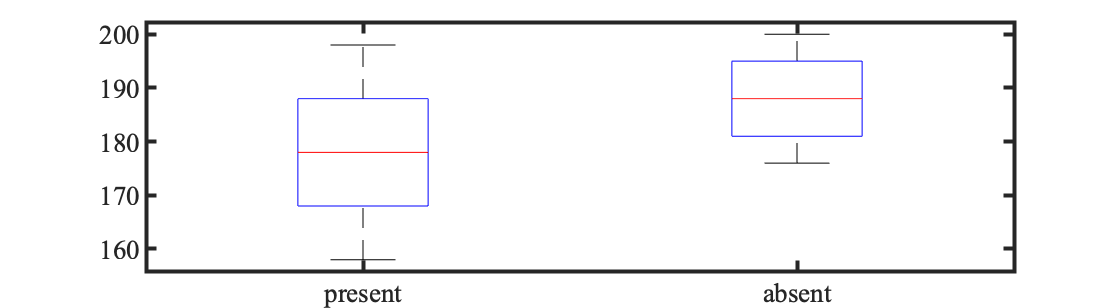

p = 0.1440

stats = struct with fields:
    chisqstat: 2.1344
           df: 1


[p, stats] = vartestn(bloodpressure', biofeedback)

## Interaction Effect, Mean Comparisons

[~, pval_nbnb_v_nbd] = ttest2(bloodpressure(1:5), bloodpressure(6:10))

pval_nbnb_v_nbd = 0.0039

[~, pval_bnd_v_bd] = ttest2(bloodpressure(11:15), bloodpressure(16:20))

pval_bnd_v_bd = 0.4468

adjusted = pval_adjust([pval_nbnb_v_nbd pval_bnd_v_bd], 'holm')

adjusted =     0.0079    0.4468


## Main Effects, Mean Comparisons

drug_main = [bloodpressure(1:5), bloodpressure(11:15)];
nodrug_main = [bloodpressure(6:10), bloodpressure(16:20)];
[~, pval_d_v_nd] = ttest2(drug_main, nodrug_main)

pval_d_v_nd = 0.0157

biof_main = bloodpressure(1:10);
nobiof_main = bloodpressure(11:20); 
[~, pval_bf_v_nbf] = ttest2(biof_main, nobiof_main)

pval_bf_v_nbf = 0.0500

## Effect Sizes

% i couldn't find any 

## Power

% i couldn't find any 

## Local Functions

function [H, pValue, W] = swtest(x, alpha)
% From https://www.mathworks.com/matlabcentral/fileexchange/13964-shapiro-wilk-and-shapiro-francia-normality-tests
%SWTEST Shapiro-Wilk parametric hypothesis test of composite normality.
%   [H, pValue, SWstatistic] = SWTEST(X, ALPHA) performs the
%   Shapiro-Wilk test to determine if the null hypothesis of
%   composite normality is a reasonable assumption regarding the
%   population distribution of a random sample X. The desired significance 
%   level, ALPHA, is an optional scalar input (default = 0.05).
%
%   The Shapiro-Wilk and Shapiro-Francia null hypothesis is: 
%   "X is normal with unspecified mean and variance."
%
%   This is an omnibus test, and is generally considered relatively
%   powerful against a variety of alternatives.
%   Shapiro-Wilk test is better than the Shapiro-Francia test for
%   Platykurtic sample. Conversely, Shapiro-Francia test is better than the
%   Shapiro-Wilk test for Leptokurtic samples.
%
%   When the series 'X' is Leptokurtic, SWTEST performs the Shapiro-Francia
%   test, else (series 'X' is Platykurtic) SWTEST performs the
%   Shapiro-Wilk test.
% 
%    [H, pValue, SWstatistic] = SWTEST(X, ALPHA)
%
% Inputs:
%   X - a vector of deviates from an unknown distribution. The observation
%     number must exceed 3 and less than 5000.
%
% Optional inputs:
%   ALPHA - The significance level for the test (default = 0.05).
%  
% Outputs:
%  SWstatistic - The test statistic (non normalized).
%
%   pValue - is the p-value, or the probability of observing the given
%     result by chance given that the null hypothesis is true. Small values
%     of pValue cast doubt on the validity of the null hypothesis.
%
%     H = 0 => Do not reject the null hypothesis at significance level ALPHA.
%     H = 1 => Reject the null hypothesis at significance level ALPHA.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                Copyright (c) 17 March 2009 by Ahmed Ben Saïda          %
%                 Department of Finance, IHEC Sousse - Tunisia           %
%                       Email: ahmedbensaida@yahoo.com                   %
%                    $ Revision 3.0 $ Date: 18 Juin 2014 $               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% References:
%
% - Royston P. "Remark AS R94", Applied Statistics (1995), Vol. 44,
%   No. 4, pp. 547-551.
%   AS R94 -- calculates Shapiro-Wilk normality test and P-value
%   for sample sizes 3 <= n <= 5000. Handles censored or uncensored data.
%   Corrects AS 181, which was found to be inaccurate for n > 50.
%   Subroutine can be found at: http://lib.stat.cmu.edu/apstat/R94
%
% - Royston P. "A pocket-calculator algorithm for the Shapiro-Francia test
%   for non-normality: An application to medicine", Statistics in Medecine
%   (1993a), Vol. 12, pp. 181-184.
%
% - Royston P. "A Toolkit for Testing Non-Normality in Complete and
%   Censored Samples", Journal of the Royal Statistical Society Series D
%   (1993b), Vol. 42, No. 1, pp. 37-43.
%
% - Royston P. "Approximating the Shapiro-Wilk W-test for non-normality",
%   Statistics and Computing (1992), Vol. 2, pp. 117-119.
%
% - Royston P. "An Extension of Shapiro and Wilk's W Test for Normality
%   to Large Samples", Journal of the Royal Statistical Society Series C
%   (1982a), Vol. 31, No. 2, pp. 115-124.
%
%
% Ensure the sample data is a VECTOR.
%
if numel(x) == length(x)
    x  =  x(:);               % Ensure a column vector.
else
    error(' Input sample ''X'' must be a vector.');
end
%
% Remove missing observations indicated by NaN's and check sample size.
%
x  =  x(~isnan(x));
if length(x) < 3
   error(' Sample vector ''X'' must have at least 3 valid observations.');
end
if length(x) > 5000
    warning('Shapiro-Wilk test might be inaccurate due to large sample size ( > 5000).');
end
%
% Ensure the significance level, ALPHA, is a 
% scalar, and set default if necessary.
%
if (nargin >= 2) && ~isempty(alpha)
   if ~isscalar(alpha)
      error(' Significance level ''Alpha'' must be a scalar.');
   end
   if (alpha <= 0 || alpha >= 1)
      error(' Significance level ''Alpha'' must be between 0 and 1.'); 
   end
else
   alpha  =  0.05;
end
% First, calculate the a's for weights as a function of the m's
% See Royston (1992, p. 117) and Royston (1993b, p. 38) for details
% in the approximation.
x       =   sort(x); % Sort the vector X in ascending order.
n       =   length(x);
mtilde  =   norminv(((1:n)' - 3/8) / (n + 1/4));
weights =   zeros(n,1); % Preallocate the weights.
if kurtosis(x) > 3
    
    % The Shapiro-Francia test is better for leptokurtic samples.
    
    weights =   1/sqrt(mtilde'*mtilde) * mtilde;
    %
    % The Shapiro-Francia statistic W' is calculated to avoid excessive
    % rounding errors for W' close to 1 (a potential problem in very
    % large samples).
    %
    W   =   (weights' * x)^2 / ((x - mean(x))' * (x - mean(x)));
    % Royston (1993a, p. 183):
    nu      =   log(n);
    u1      =   log(nu) - nu;
    u2      =   log(nu) + 2/nu;
    mu      =   -1.2725 + (1.0521 * u1);
    sigma   =   1.0308 - (0.26758 * u2);
    newSFstatistic  =   log(1 - W);
    %
    % Compute the normalized Shapiro-Francia statistic and its p-value.
    %
    NormalSFstatistic =   (newSFstatistic - mu) / sigma;
    
    % Computes the p-value, Royston (1993a, p. 183).
    pValue   =   1 - normcdf(NormalSFstatistic, 0, 1);
    
else
    
    % The Shapiro-Wilk test is better for platykurtic samples.
    c    =   1/sqrt(mtilde'*mtilde) * mtilde;
    u    =   1/sqrt(n);
    % Royston (1992, p. 117) and Royston (1993b, p. 38):
    PolyCoef_1   =   [-2.706056 , 4.434685 , -2.071190 , -0.147981 , 0.221157 , c(n)];
    PolyCoef_2   =   [-3.582633 , 5.682633 , -1.752461 , -0.293762 , 0.042981 , c(n-1)];
    % Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1)
    PolyCoef_3   =   [-0.0006714 , 0.0250540 , -0.39978 , 0.54400];
    PolyCoef_4   =   [-0.0020322 , 0.0627670 , -0.77857 , 1.38220];
    PolyCoef_5   =   [0.00389150 , -0.083751 , -0.31082 , -1.5861];
    PolyCoef_6   =   [0.00303020 , -0.082676 , -0.48030];
    PolyCoef_7   =   [0.459 , -2.273];
    weights(n)   =   polyval(PolyCoef_1 , u);
    weights(1)   =   -weights(n);
    
    if n > 5
        weights(n-1) =   polyval(PolyCoef_2 , u);
        weights(2)   =   -weights(n-1);
    
        count  =   3;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2 - 2 * mtilde(n-1)^2) / ...
                (1 - 2 * weights(n)^2 - 2 * weights(n-1)^2);
    else
        count  =   2;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2) / ...
                (1 - 2 * weights(n)^2);
    end
        
    % Special attention when n = 3 (this is a special case).
    if n == 3
        % Royston (1992, p. 117)
        weights(1)  =   1/sqrt(2);
        weights(n)  =   -weights(1);
        phi = 1;
    end
    %
    % The vector 'WEIGHTS' obtained next corresponds to the same coefficients
    % listed by Shapiro-Wilk in their original test for small samples.
    %
    weights(count : n-count+1)  =  mtilde(count : n-count+1) / sqrt(phi);
    %
    % The Shapiro-Wilk statistic W is calculated to avoid excessive rounding
    % errors for W close to 1 (a potential problem in very large samples).
    %
    W   =   (weights' * x) ^2 / ((x - mean(x))' * (x - mean(x)));
    %
    % Calculate the normalized W and its significance level (exact for
    % n = 3). Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1).
    %
    newn    =   log(n);
    if (n >= 4) && (n <= 11)
    
        mu      =   polyval(PolyCoef_3 , n);
        sigma   =   exp(polyval(PolyCoef_4 , n));    
        gam     =   polyval(PolyCoef_7 , n);
    
        newSWstatistic  =   -log(gam-log(1-W));
    
    elseif n > 11
    
        mu      =   polyval(PolyCoef_5 , newn);
        sigma   =   exp(polyval(PolyCoef_6 , newn));
    
        newSWstatistic  =   log(1 - W);
    
    elseif n == 3
        mu      =   0;
        sigma   =   1;
        newSWstatistic  =   0;
    end
    %
    % Compute the normalized Shapiro-Wilk statistic and its p-value.
    %
    NormalSWstatistic   =   (newSWstatistic - mu) / sigma;
    
    % NormalSWstatistic is referred to the upper tail of N(0,1),
    % Royston (1992, p. 119).
    pValue       =   1 - normcdf(NormalSWstatistic, 0, 1);
    
    % Special attention when n = 3 (this is a special case).
    if n == 3
        pValue  =   6/pi * (asin(sqrt(W)) - asin(sqrt(3/4)));
        % Royston (1982a, p. 121)
    end
    
end
%
% To maintain consistency with existing Statistics Toolbox hypothesis
% tests, returning 'H = 0' implies that we 'Do not reject the null 
% hypothesis at the significance level of alpha' and 'H = 1' implies 
% that we 'Reject the null hypothesis at significance level of alpha.'
%
H  = (alpha >= pValue);
end

function pc = pval_adjust(p, method)
% PVAL_ADJUST Adjust p-values for multiple comparisons. Given a set of
% p-values, returns p-values adjusted using one of several methods. This is
% an implementation of the p.adjust R function, the documentation of which
% can be found at http://www.inside-r.org/r-doc/stats/p.adjust.
%
%   pc = PVAL_ADJUST(p, method)
%
% Parameters:
%        p - Numeric vector or matrix of p-values. Contrary to the R
%            function, this function does not handle missing values.
%   method - Correction method, one of: 'holm', 'hochberg', 'hommel', 
%            'bonferroni', 'BH', 'BY', 'fdr', 'sidak' or 'none'.
%
% Outputs:
%       pc - A numeric vector or matrix of corrected p-values, with the
%            same shape/dimensions of p.
%
% Notes:
%
% This function has two main differences regarding the R implementation:
%
%   1. Contrary to the R function, this function does not handle missing
%      values.
%   2. It adds one additional correction method, 'sidak', as described
%      here: https://en.wikipedia.org/wiki/%C5%A0id%C3%A1k_correction
%
%
% Copyright (c) 2016 Nuno Fachada
% Distributed under the MIT License (See accompanying file LICENSE or copy 
% at http://opensource.org/licenses/MIT)
%
% Number of p-values
np = numel(p);
% Reshape input into a row vector, keeping original shape for later
% converting results into original shape
pdims = size(p);
p = reshape(p, 1, np);
% Method 'hommel' is equivalent to 'hochberg' of np == 2
if (np == 2) &&  strcmp(method, 'hommel')
    method = 'hochberg';
end
% Just one p-value? Return it as given.
if np <= 1
    pc = p;
    
% What method to use?
elseif strcmp(method, 'holm')
    
    % Sort p-values from smallest to largest
    [pc, pidx] = sort(p);
    [~, ipidx] = sort(pidx);
    
    % Adjust p-values
    pc = min(1, cmax((np - (1:np) + 1) .* pc));
    
    % Put p-values back in original positions
    pc = pc(ipidx);
elseif strcmp(method, 'hochberg')
    % Descendent vector
    vdec = np:-1:1;
    
    % Sort p-values in descending order
    [pc, pidx] = sort(p, 'descend');
    
    % Get indexes of p-value indexes
    [~, ipidx] = sort(pidx);
    
    % Hochberg-specific transformation
    pc = ((np + 1) - vdec) .* pc;
    % Cumulative minimum
    pc = cmin(pc);
    
    % Reorder p-values to original order
    pc = pc(ipidx);
elseif strcmp(method, 'hommel')
    % Sort p-values from smallest to largest
    [pc, pidx] = sort(p);
    
    % Get indexes of p-value indexes
    [~, ipidx] = sort(pidx);
    
    % Generate vectors for cycle
    pa = repmat(min(np * pc ./ (1:np)), size(p));
    q = pa;
    
    % Begin cycle
    for i = (np - 1):-1:2
        i1 = 1:(np - i + 1);
        i2 = (np - i + 2):np;
        q1 = min(i * pc(i2) ./ (2:i));
        q(i1) = min(i * pc(i1), q1);
        q(i2) = q(np - i + 1);
        pa = max(pa, q);
    end
    
    % Finalize result
    pa = max(pa, pc);
    pc = pa(ipidx);
elseif strcmp(method, 'bonferroni')
    
    % Simple conservative Bonferroni
    pc = p * numel(p);
elseif strcmp(method, 'BH') || strcmp(method, 'fdr')
    % Descendent vector
    vdec = np:-1:1;
    
    % Sort p-values in descending order
    [pc, pidx] = sort(p, 'descend');
    % Get indexes of p-value indexes
    [~, ipidx] = sort(pidx);
    % BH-specific transformation
    pc = (np ./ vdec) .* pc;
    % Cumulative minimum
    pc = cmin(pc);    
    
    % Reorder p-values to original order
    pc = pc(ipidx);
elseif strcmp(method, 'BY')
    % Descendent vector
    vdec = np:-1:1;
    
    % Sort p-values in descending order
    [pc, pidx] = sort(p, 'descend');
    % Get indexes of p-value indexes
    [~, ipidx] = sort(pidx);
    % BY-specific transformation
    q = sum(1 ./ (1:np));
    pc = (q * np ./ vdec) .* pc;
    % Cumulative minimum
    pc = cmin(pc);    
    
    % Reorder p-values to original order
    pc = pc(ipidx);
elseif strcmp(method, 'sidak')
    % Sidak correction
    pc = 1 - (1 - p) .^ np;
    
elseif strcmp(method, 'none')
    
    % No correction
    pc = p;
    
else
    
    % Unknown method
    error('Unknown p-value adjustment method');
   
end
% Can't have p-values larger than one
pc(pc > 1) = 1;    
% Reshape result vector to original form
pc = reshape(pc, pdims);
% Helper function to determine the cumulative maximum
function p = cmax(p)
for i = 2:numel(p)
    if p(i) < p(i - 1)
        p(i) = p(i - 1);
    end
end
% Helper function to determine the cumulative minimum
function p = cmin(p)
for i = 2:numel(p)
    if p(i) > p(i - 1)
        p(i) = p(i - 1);
    end
end
end
end
end
